## La serie de Taylor como aproximación

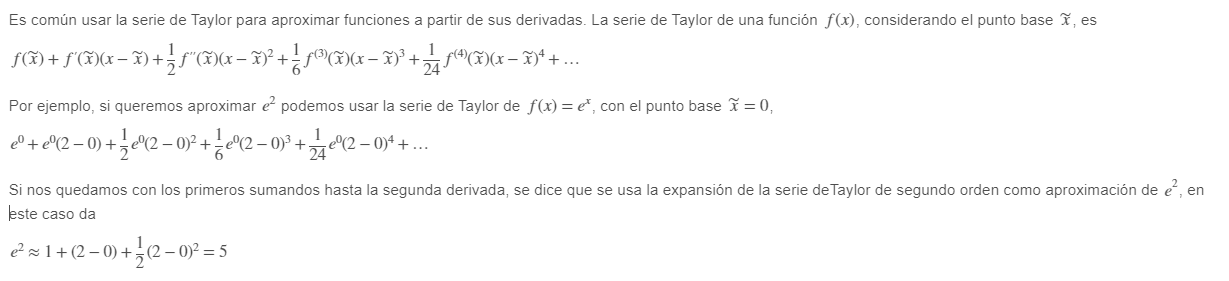

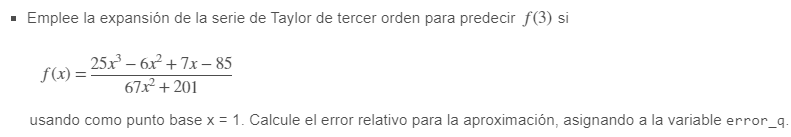

format long

a = 3;
syms x;

f_1 = (25*(x^3)-6*(x^2)+7*x-85)/(67*(x^2)+201)

$$f\_1 = \frac{25\,x^{3}-6\,x^{2}+7\,x-85}{67\,x^{2}+201}$$

f_1_aprox = taylor(f_1, x, 'ExpansionPoint', 1, 'Order', 4)

$$f\_1\_aprox = \frac{199\,x}{536}+\frac{17\,{\left(x-1\right)}^{2}}{134}-\frac{135\,{\left(x-1\right)}^{3}}{2144}-\frac{317}{536}$$

f_1_aprox = double(subs(f_1_aprox, x, a))

f_1_aprox =    0.526119402985075


f_1_exacto = double(subs(f_1, a))

f_1_exacto =    0.692786069651741


error_q = abs(f_1_exacto - f_1_aprox) / abs(f_1_exacto)

error_q =    0.240574506283662


a = 2;
syms x;

f_2 = log(x)

$$f\_2 = \log\left(x\right)$$

f_2_aprox = taylor(f_2, x,'ExpansionPoint', 1, 'Order', 5)

$$f\_2\_aprox = x-\frac{{\left(x-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{3}}{3}-\frac{{\left(x-1\right)}^{4}}{4}-1$$

f_2_aprox = double(subs(f_2_aprox, x, a))

f_2_aprox =    0.583333333333333


f_2_exacto = double(subs(f_2, a))

f_2_exacto =    0.693147180559945


error_ln = abs(f_2_exacto - f_2_aprox) / abs(f_2_exacto)

error_ln =    0.158427892814771


ind=0;

if(error_ln<error_q) 
    ind=1;
end

ind

ind =      1
